clc, clear, clearvars


# **MAX2821: Up/Down Converter Chip**

The overall purpose of this chip is to convert the high frequency 2.5GHz signal from the antenna, down to a lower Baseband (BB) frequency of 20MHz. In principal, this means the maximum baseband bandwidth (BW) is 20MHz. This document will attempt to outline a basic understanding of how this chip works.

% Specifications from MAX2821 datasheet
RF_GAIN = 20;           % RF gain in dB (typical)
NF = 4.5;              % Noise Figure in dB
IP3 = -8;              % Input IP3 in dBm
RF_FREQ = 2.45e9;
IF_BANDWIDTH = 20e6;   % IF bandwidth
LO_FREQ = RF_FREQ-IF_BANDWIDTH;      % Local oscillator frequency (center of band)
t = linspace(-1,1, 10e3)

t =    -1.0000   -0.9998   -0.9996   -0.9994   -0.9992   -0.9990   -0.9988   -0.9986   -0.9984   -0.9982   -0.9980   -0.9978   -0.9976   -0.9974   -0.9972   -0.9970   -0.9968   -0.9966   -0.9964   -0.9962   -0.9960   -0.9958   -0.9956   -0.9954   -0.9952   -0.9950   -0.9948   -0.9946   -0.9944   -0.9942   -0.9940   -0.9938   -0.9936   -0.9934   -0.9932   -0.9930   -0.9928   -0.9926   -0.9924   -0.9922   -0.9920   -0.9918   -0.9916   -0.9914   -0.9912   -0.9910   -0.9908   -0.9906   -0.9904   -0.9902


WRF = 2*pi*RF_FREQ;w=WRF

w = 1.5394e+10


% Approximate the amount of noise we can expect and simulate how the model
% will handle that noise
kT = -174;             % Thermal noise in dBm/Hz
noise_power = kT + NF + 10*log10(IF_BANDWIDTH);
noise = sqrt(10^(noise_power/10)/2) * (randn(size(t)) + 1j*randn(size(t)));

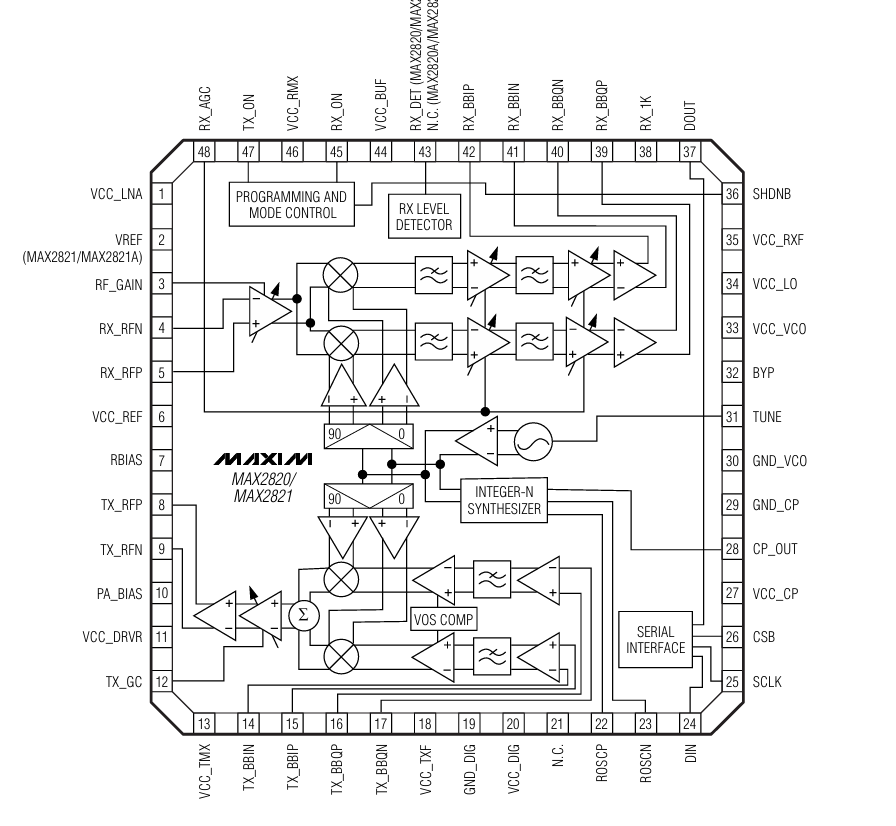

First we will define the input of the system, for now we will consider the simple sinusoidal wave. One way to express this sinusoidal primitive is to observe euler's idenity.


$$\begin{array}{l}
e^{\mathrm{jwt}} =\cos \left(\mathrm{wt}\right)+\mathrm{jsin}\left(\mathrm{wt}\right)\\

\end{array}$$


%Define the incoming rf signal
%ex:
rf_signal = @(w) exp(j*w*t);

Since this is in the complex domain, we often refer t

% We can define the input in terms of IQ pairs
%We call the real part I
I = real(rf_signal(WRF));
% And the imaginary part Q
Q = imag(rf_signal(WRF));



% RF Amplifier stage
% add in the thermal noise considerations for said amp stage
amp_signal = (rf_signal+noise) * 10^(RF_GAIN/20);


% Mixer stage - downconvert to IF
lo_signal = exp(-1j*2*pi*LO_FREQ*t);
if_signal = rf_signal .* lo_signal;

% IF Filter (implement as lowpass)
[b, a] = butter(6, IF_BANDWIDTH/(sampling_rate/2));
if_filtered = filter(b, a, if_signal);

% Variable Gain Amplifier (VGA)
% Assuming AGC sets appropriate gain
vga_gain = 20;  % dB, adjustable from 0 to 60dB
output_signal = if_filtered * 10^(vga_gain/20);

% Add nonlinearity effects
% Simplified third-order nonlinearity
output_signal = output_signal - 0.1 * abs(output_signal).^2 .* output_signal;